# Lecture 6: Spatial Filtering

# Part 2: Sharpening Filters

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture6 - Spatial Filtering

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

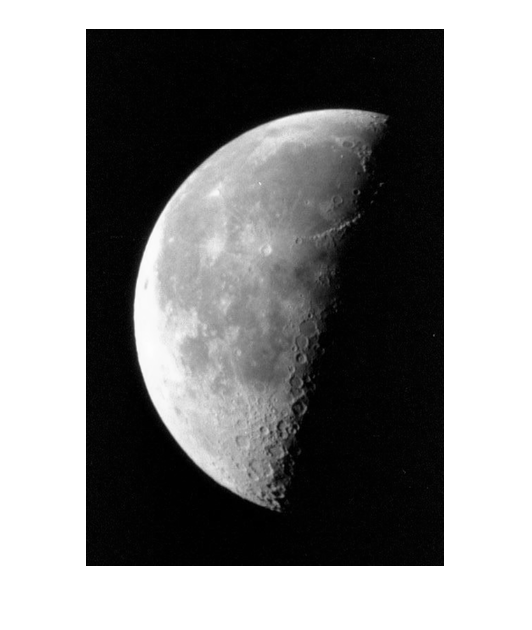

% read input image
I = imread('images/moon.tif');
imshow(I)

## Laplacian filtering

f=fspecial('laplacian')

f =     0.1667    0.6667    0.1667
    0.6667   -3.3333    0.6667
    0.1667    0.6667    0.1667


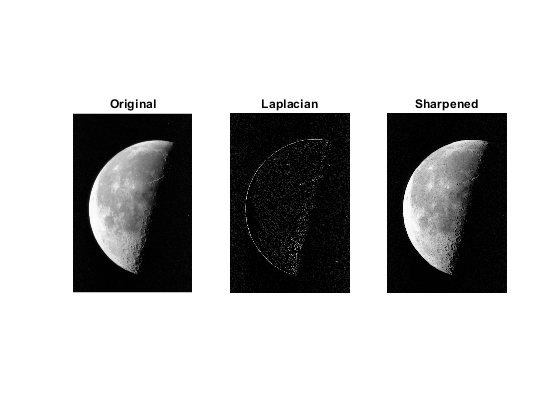

%f=[0 1 0; 1 -4 1; 0 1 0]

Ilap=imfilter(I,f);
Isharp=imsubtract(I,Ilap);

figure, subplot(1,3,1),imshow(I), title('Original')
subplot(1,3,2), imshow(Ilap,[]), title('Laplacian')
subplot(1,3,3), imshow(Isharp), title('Sharpened');

## Unsharp masking (manual)

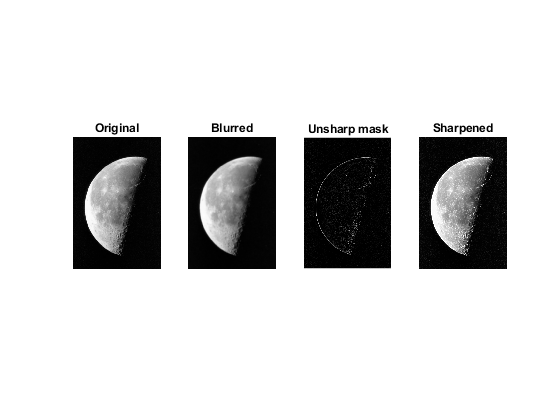

w=5; %size of blurring filter
k=3; %coefficient for unsharp masking

f=fspecial('average',w); %create a blurring filter, you can also use other blurring filters
Iavg=imfilter(I,f); %blur the original image

UM = imsubtract(I,Iavg); %subtract blurred image from the original

Iout = imadd(I,(k*UM)); %add the resulting unsharp mask to original image

%display
figure, subplot(1,4,1), imshow(I), title('Original');
subplot(1,4,2), imshow(Iavg), title('Blurred');
subplot(1,4,3), imshow(UM,[]), title('Unsharp mask');
subplot(1,4,4), imshow(Iout), title('Sharpened');

## Sharpening (imsharpen)

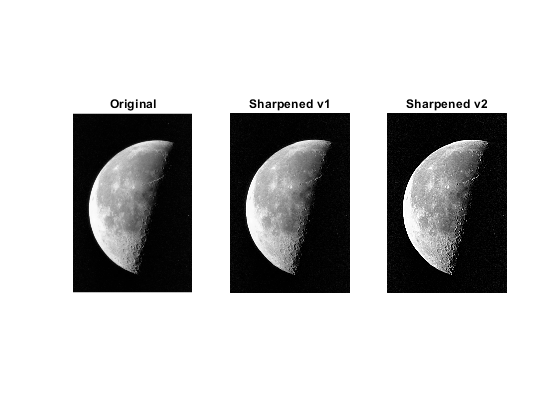

I1 = imsharpen(I);
I2 = imsharpen(I,'Radius',2,'Amount',2);

figure, subplot(1,3,1), imshow(I), title('Original')
subplot(1,3,2), imshow(I1), title('Sharpened v1')
subplot(1,3,3), imshow(I2), title('Sharpened v2')